# Control de posición del variador-motor por realimentación de estados

# 1. Modelo matemático de la planta

El modelo matemático de la planta se obtuvo de forma experimental. El modelo obtenido es una función de transferencia, donde se está suponiendo que el conjunto variador-motor es lineal y estacionario. El procedimiento por el cual se obtuvo el modelo se detalla en la bitácora de caracterización de la planta. Dicho modelo relaciona la velocidad angular (salida) del eje del motor y la tensión aplicada a la entrada analógica del variador de frecuencia (VFD).

## 1.1 Función de transferencia

Entrada de la función de transferencia experimental es voltaje y la salida velocidad angular [rad/seg]. La funcion que se obtuvo es como sigue:


$$\frac{\Omega \left(s\right)}{V\left(s\right)}=\frac{26\ldotp 55}{s^2 +5\ldotp 163*s+15\ldotp 58}\;\left\lbrack \frac{\mathrm{rad}/\mathrm{seg}}{V}\right\rbrack$$


f_motor_rad=tf(26.55,[1 5.163 15.58])


f_motor_rad =
 
          26.55
  ---------------------
  s^2 + 5.163 s + 15.58
 
Continuous-time transfer function.



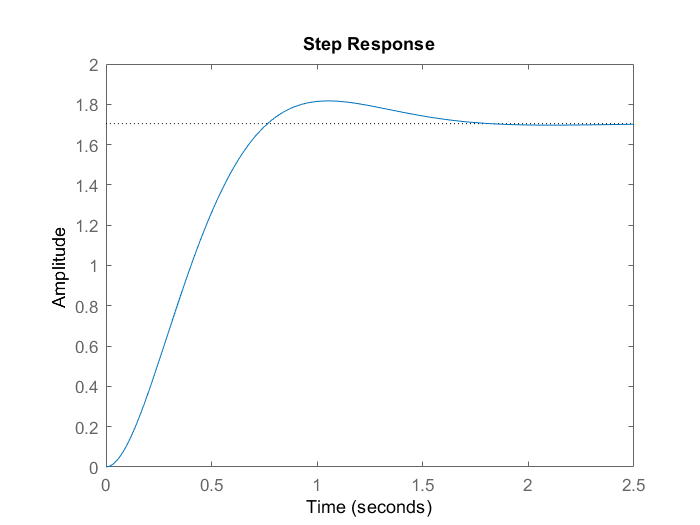

step(f_motor_rad)

Entrada de la TF voltaje y salida velocidad angular en grados sexagesimales

f_motor_grad=tf(26.55,[1 5.163 15.58])*(180/pi)


f_motor_grad =
 
          1521
  ---------------------
  s^2 + 5.163 s + 15.58
 
Continuous-time transfer function.



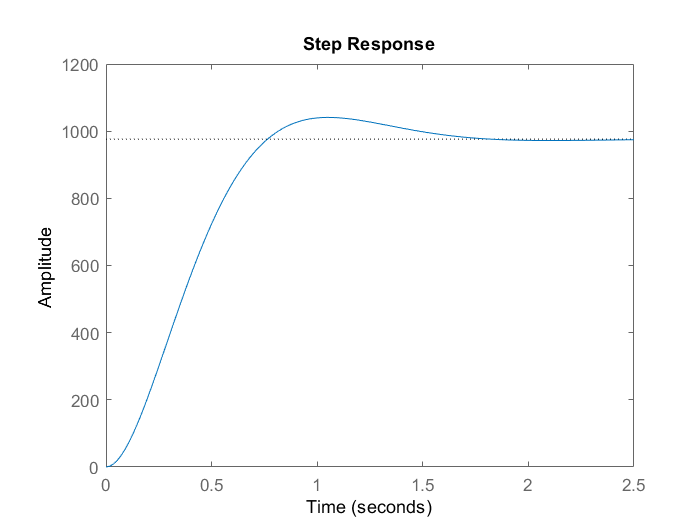

step(10*f_motor_grad)

Entrada de la TF voltaje y salida posicion angular en radianes


$$\frac{\Omega \left(s\right)}{V\left(s\right)}=\frac{\Theta^˙ \left(s\right)}{V\left(s\right)}=\frac{26\ldotp 55}{s^2 +5\ldotp 163*s+15\ldotp 58}\;\left\lbrack \frac{\mathrm{rad}/\mathrm{seg}}{V}\right\rbrack$$


Como:


$$\Theta^˙ \left(s\right)=s\Theta \left(s\right)-\theta \left(0\right)$$


Con condiciones iniciales nulas:


$$\Theta^˙ \left(s\right)=s\Theta \left(s\right)$$


s=tf('s');  
pos_mot_rad=f_motor_rad/s


pos_mot_rad =
 
            26.55
  -------------------------
  s^3 + 5.163 s^2 + 15.58 s
 
Continuous-time transfer function.



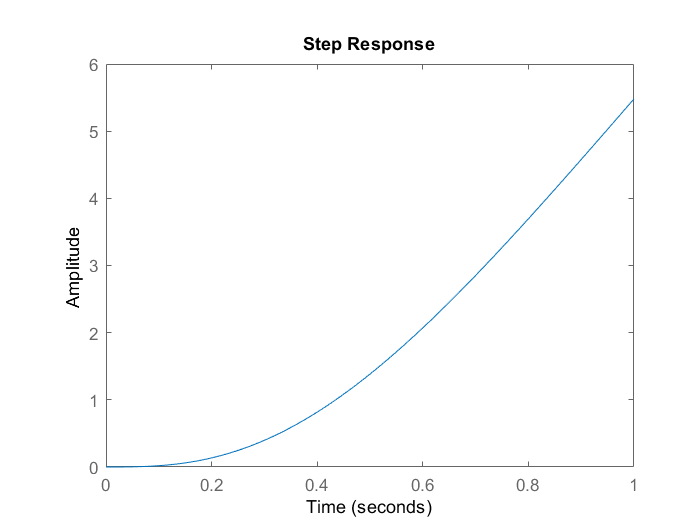

step(5*pos_mot_rad,1)

Entrada de la TF voltaje y salida longitud de arco (posicion lineal de la correa transportadora)

Se determino que el radio del eje que sujeta la correa es:


$$r=1\ldotp 8382\;\left\lbrack \mathrm{cm}\right\rbrack$$


Sabiendo que la longitud de arco es igual a:


$$S=r\;\theta$$


Por lo tanto:


$$\frac{L\left(s\right)}{V\left(s\right)}=\frac{26\ldotp 55}{s^3 +5\ldotp 163*s^2 +15\ldotp 58*s}*1\ldotp 8382\left\lbrack \frac{\mathrm{cm}}{V}\right\rbrack$$


pos_mot=pos_mot_rad*1.8382


pos_mot =
 
            48.8
  -------------------------
  s^3 + 5.163 s^2 + 15.58 s
 
Continuous-time transfer function.



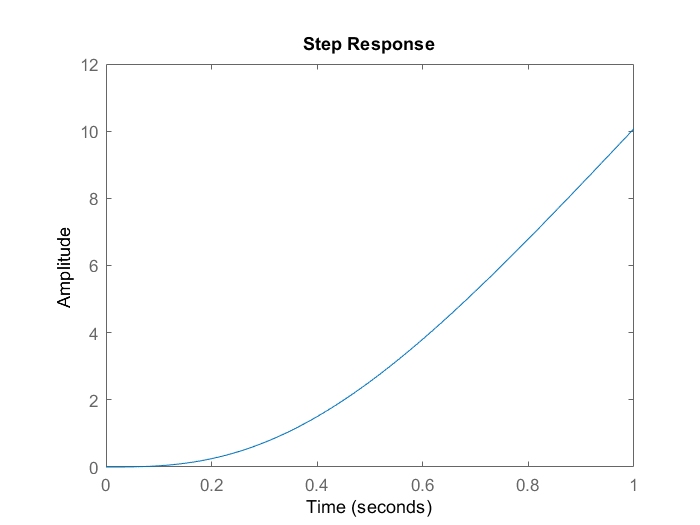

step(5*pos_mot,1)

[num,den]=tfdata(pos_mot);
num=cell2mat(num);
den=cell2mat(den);
a=num(4)

a = 48.8042

b=den(2)

b = 5.1630

c=den(3)

c = 15.5800


A=[0 1 0
   0 0 1
   0 -c -b]

A =          0    1.0000         0
         0         0    1.0000
         0  -15.5800   -5.1630


B=[0
   0
   a]

B =          0
         0
   48.8042


C=[1 0 0]

C =      1     0     0



D=[0]

D = 0

step(5*ss(A,B,C,D),1)

%"Requerimientos temporales"
ts=4;
zeta_d=1.3;
wn_d=3.3*2*zeta_d/ts

wn_d = 2.1450


Gd=wn_d^2/(s^2+2*zeta_d*wn_d*s+wn_d^2)


Gd =
 
          4.601
  ---------------------
  s^2 + 5.577 s + 4.601
 
Continuous-time transfer function.



p=pole(Gd)

p =    -4.5703
   -1.0067


stepinfo(Gd)

ans = struct with fields:
        RiseTime: 2.2726
    SettlingTime: 4.1330
     SettlingMin: 0.9005
     SettlingMax: 0.9998
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9998
        PeakTime: 8.6455



%Controlabilidad
C_cont=[B A*B A^2*B]

C_cont =          0         0   48.8042
         0   48.8042 -251.9761
   48.8042 -251.9761  540.5832


rank(C_cont)

ans = 3


%Ecuacion propia
H=conv([1 -p(1)],[1 -p(2)])

H =     1.0000    5.5770    4.6010


H=conv(H,[1 15])

H =     1.0000   20.5770   88.2560   69.0154


%Formula de Ackermman
eq_propia=H(1)*A^3+H(2)*A^2+H(3)*A+H(4)*eye(3)

eq_propia =    69.0154   72.6760   15.4140
         0 -171.1347   -6.9065
         0  107.6026 -135.4767


K=[0 0 1]*inv(C_cont)*eq_propia

K =     1.4141    1.4891    0.3158


%simulacion (sin observador)
sys=ss(A-B*K,B*K(1),C,D)


sys =
 
  A = 
           x1      x2      x3
   x1       0       1       0
   x2       0       0       1
   x3  -69.02  -88.26  -20.58
 
  B = 
          u1
   x1      0
   x2      0
   x3  69.02
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



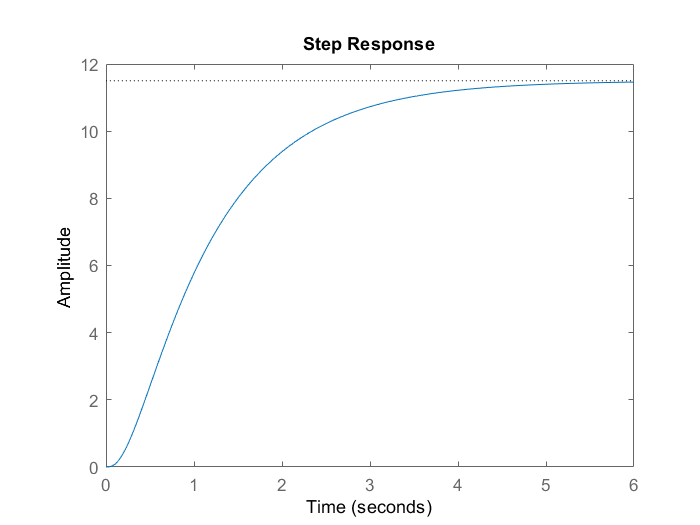

step(11.5*sys)

stepinfo(sys)

ans = struct with fields:
        RiseTime: 2.2794
    SettlingTime: 4.2021
     SettlingMin: 0.9016
     SettlingMax: 0.9986
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9986
        PeakTime: 6.8318


%Observador

%Orden reducido
Aaa=A(1,1)

Aaa = 0

Aab=A(1,2:3)

Aab =      1     0


Aba=A(2:3,1)

Aba =      0
     0


Abb=A(2:3,2:3)

Abb =          0    1.0000
  -15.5800   -5.1630



%Formula de Ackermman
phi_1=[1 5] %6.5

phi_1 =      1     5


phi=conv(phi_1,phi_1)

phi =      1    10    25


Ke=(phi(1)*Abb^2 + phi(2)*Abb + phi(3)*eye(2))*inv([Aab;Aab*Abb])*[0;1]

Ke =     4.8370
  -15.5534


Ka=K(1);
Kb=K(2:3);
Ba=[0];
Bb=B(2:3);

%Funcion de transferencia Controlador-observador
Ahat= Abb - Ke*Aab;
Bhat= Ahat*Ke + Aba - Ke*Aaa;
Fhat=Bb - Ke*Ba;
Atilde=Ahat - Fhat*Kb;
Btilde=Bhat - Fhat*(Ka + Kb*Ke);
Ctilde=-Kb;
Dtilde=-(Ka + Kb*Ke);
[num,den]=ss2tf(Atilde,Btilde,-Ctilde,-Dtilde)

num =     3.7048    4.3676   35.3532


den =     1.0000   25.4140  172.2335


controlador=tf(num,den)


controlador =
 
  3.705 s^2 + 4.368 s + 35.35
  ---------------------------
     s^2 + 25.41 s + 172.2
 
Continuous-time transfer function.



pole(controlador)

ans =  -12.7070 + 3.2811i
 -12.7070 - 3.2811i


zero(controlador)

ans =   -0.5895 + 3.0323i
  -0.5895 - 3.0323i


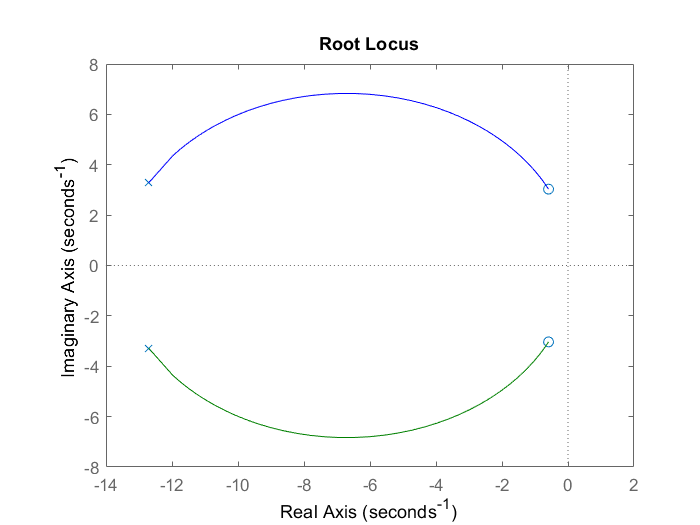

rlocus(controlador)


%Simulacion
pos_mot


pos_mot =
 
            48.8
  -------------------------
  s^3 + 5.163 s^2 + 15.58 s
 
Continuous-time transfer function.



G_final=feedback(controlador*pos_mot,1)


G_final =
 
               180.8 s^2 + 213.2 s + 1725
  ----------------------------------------------------
  s^5 + 30.58 s^4 + 319 s^3 + 1466 s^2 + 2897 s + 1725
 
Continuous-time transfer function.



pole(G_final)

ans =   -15.0000
   -5.0000
   -5.0000
   -4.5703
   -1.0067


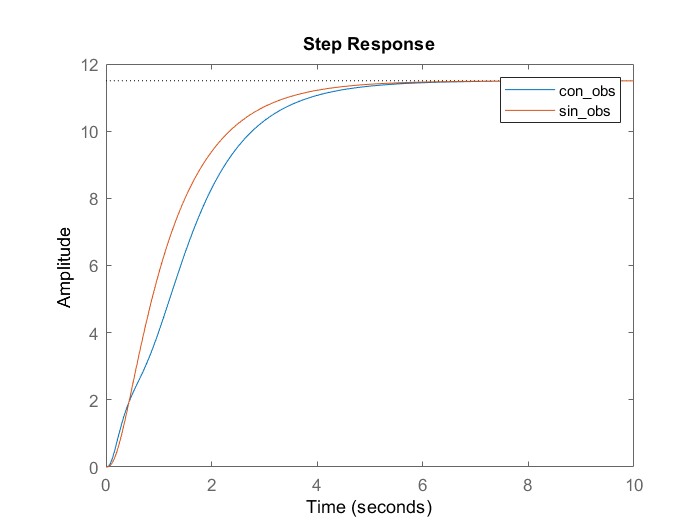

step(11.5*G_final,10)
hold on
step(11.5*sys,10)
hold off
legend('con_obs','sin_obs')

stepinfo(G_final)

ans = struct with fields:
        RiseTime: 2.7577
    SettlingTime: 4.6305
     SettlingMin: 0.9002
     SettlingMax: 0.9997
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9997
        PeakTime: 8.6556


pole(G_final)

ans =   -15.0000
   -5.0000
   -5.0000
   -4.5703
   -1.0067


Para simulink continuo:

[num_c,den_c]=tfdata(controlador)

num_c = 1×1 cell array
    {1×3 double}


den_c = 1×1 cell array
    {1×3 double}


num_c=cell2mat(num_c)

num_c =     3.7048    4.3676   35.3532


den_c=cell2mat(den_c)

den_c =     1.0000   25.4140  172.2335



[num_p,den_p]=tfdata(pos_mot);
num_p=cell2mat(num_p);
den_p=cell2mat(den_p);

Discretizar

wm=bandwidth(feedback(pos_mot,1))

wm = 4.6517

Nm=50;
Ts=2*pi/(wm*Nm)

Ts = 0.0270

Ts=27e-3

Ts = 0.0270

pos_mot_discreto=c2d(pos_mot,Ts,'zoh')


pos_mot_discreto =
 
  0.0001546 z^2 + 0.000597 z + 0.0001442
  --------------------------------------
    z^3 - 2.859 z^2 + 2.729 z - 0.8699
 
Sample time: 0.027 seconds
Discrete-time transfer function.



[num1,den1]=tfdata(pos_mot_discreto);
num1=cell2mat(num1)

num1 = 	1.0e+-3 *

         0    0.1546    0.5970    0.1442


den1=cell2mat(den1)

den1 =     1.0000   -2.8593    2.7292   -0.8699


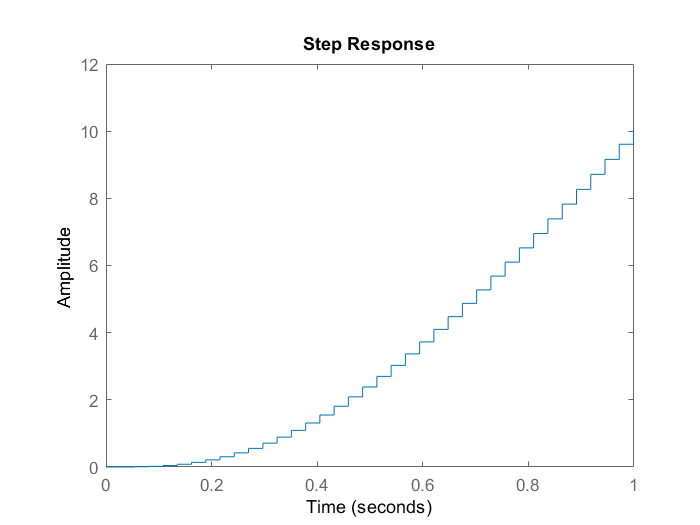

step(5*pos_mot_discreto,1)


controlador_discreto=c2d(controlador,Ts,'tustin')


controlador_discreto =
 
  2.743 z^2 - 5.381 z + 2.657
  ---------------------------
    z^2 - 1.409 z + 0.5008
 
Sample time: 0.027 seconds
Discrete-time transfer function.



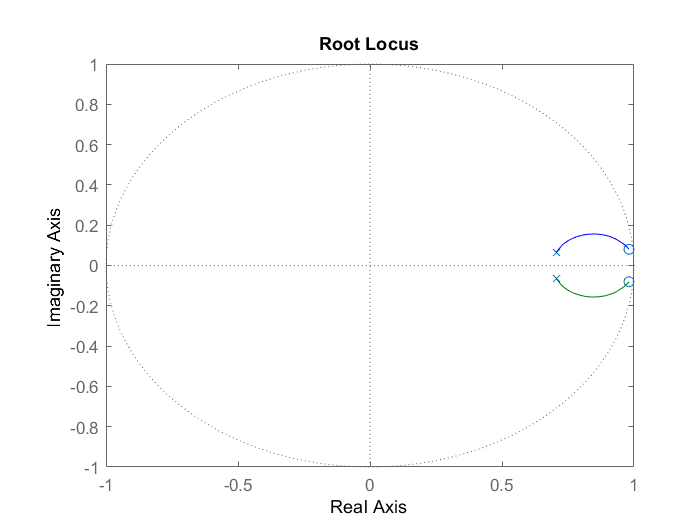

rlocus(controlador_discreto)


G_final_discreto=feedback(controlador_discreto*pos_mot_discreto,1)


G_final_discreto =
 
  0.000424 z^4 + 0.0008058 z^3 - 0.002407 z^2 + 0.0008106 z + 0.0003831
  ---------------------------------------------------------------------
       z^5 - 4.268 z^4 + 7.261 z^3 - 6.151 z^2 + 2.594 z - 0.4352
 
Sample time: 0.027 seconds
Discrete-time transfer function.



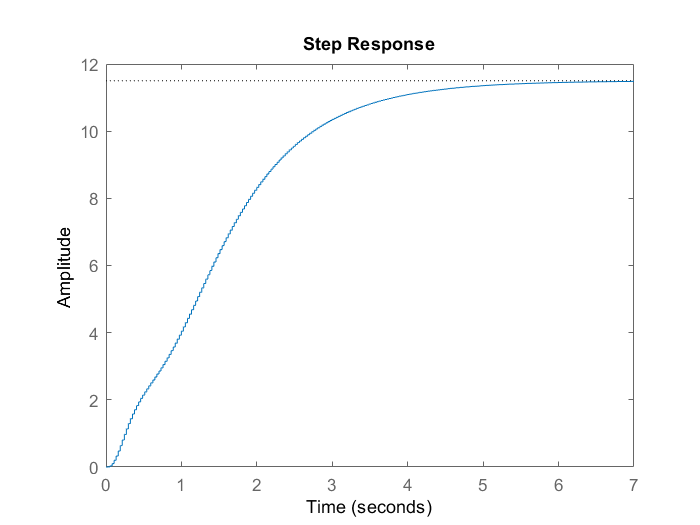


step(11.5*G_final_discreto)

Ecuacion de recurrencia

controlador_discreto


controlador_discreto =
 
  2.743 z^2 - 5.381 z + 2.657
  ---------------------------
    z^2 - 1.409 z + 0.5008
 
Sample time: 0.027 seconds
Discrete-time transfer function.



[num,den]=tfdata(controlador_discreto);
num=cell2mat(num)

num =     2.7430   -5.3814    2.6572


den=cell2mat(den)

den =     1.0000   -1.4094    0.5008



a=num(1);
b=-num(2);
c=num(3);
d=den(1);
e=-den(2);
f=den(3);

Coeficientes de la ecuacion en recurrencia:

A=e/d

A = 1.4094

B=f/d

B = 0.5008

C=c/d

C = 2.7430

D=b/d

D = 5.3814

E=a/d

E = 2.6572

Para simulink discreto:

[num1,den1]=tfdata(pos_mot_discreto);
num1=cell2mat(num1)

num1 = 	1.0e+-3 *

         0    0.1546    0.5970    0.1442


den1=cell2mat(den1)

den1 =     1.0000   -2.8593    2.7292   -0.8699


Contrastar datos con la simulacion:

1. Ejecutar simulink "discreto.slx"

2. Importar datos de** ALL0006**

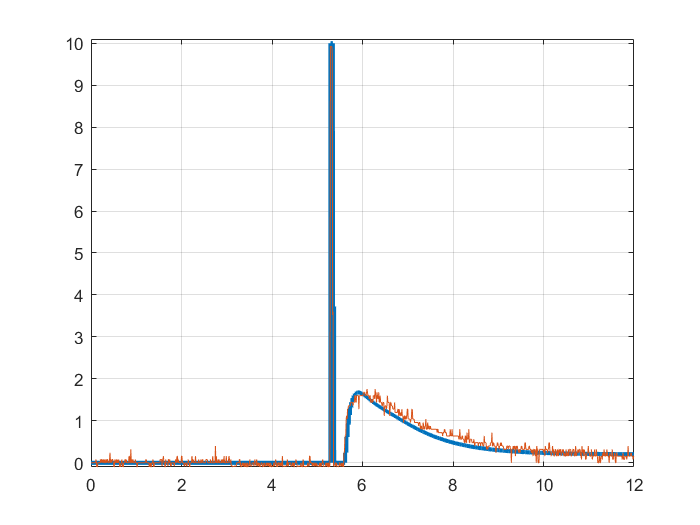

Vs=2; %escala vertical del osciloscopio
Tsampling=1e-2;
clear to
to(1)=0;
for i=2:length(Source)
    to(i)=to(i-1)+Tsampling;
end
plot(simout.time,simout.signals.values,'LineWidth',2.5)
hold on
ta=find(to>=12);
plot(to(1:ta(1)),Source(1:ta(1))*Vs/25)
axis([0 12 -0.1 10.1])
grid on
hold off